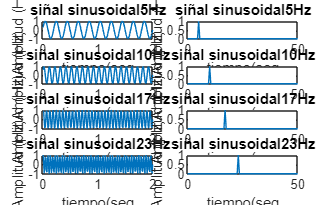

fs = 100; 
f1 = 5;
f2 = 10;
f3 = 17;
f4 = 23;
t = 1/fs:1/fs:2;
t2= 1/fs:1/fs:8;
F= fs*(0:((fs*t(end))/2))/(fs*t(end));
F2= fs*(0:((fs*t2(end))/2))/(fs*t2(end));
s1 = sin(2*pi*f1*t);
s2 = sin(2*pi*f2*t);
s3 = sin(2*pi*f3*t);
s4= sin(2*pi*f4*t);

figure('Name','señales sinusoidales','units',...
    'normalized','outerposition',[0 0 1 1])

subplot(4,2,1)
plot(t,s1)
title(['siñal sinusoidal',num2str(f1),'Hz']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

subplot(4,2,3)
plot(t,s2)
title(['siñal sinusoidal',num2str(f2),'Hz']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

subplot(4,2,5)
plot(t,s3)
title(['siñal sinusoidal',num2str(f3),'Hz']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

subplot(4,2,7)
plot(t,s4)
title(['siñal sinusoidal',num2str(f4),'Hz']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

four1 = fft(s1);
four2 = fft(s2);
four3 = fft(s3);
four4 = fft(s4);

mag1 = abs(four1/(fs*t(end)));
mag2 = abs(four2/(fs*t(end)));
mag3 = abs(four3/(fs*t(end)));
mag4 = abs(four4/(fs*t(end)));

norm1 = mag1(1:(fs*t(end))/2+1);
norm1(2:end-1) = 2*norm1(2:end-1);

norm2 = mag2(1:(fs*t(end))/2+1);
norm2(2:end-1) = 2*norm2(2:end-1);

norm3 = mag3(1:(fs*t(end))/2+1);
norm3(2:end-1) = 2*norm3(2:end-1);

norm4 = mag4(1:(fs*t(end))/2+1);
norm4(2:end-1) = 2*norm4(2:end-1);

subplot(4,2,2)
plot(F,norm1)
title(['siñal sinusoidal',num2str(f1),'Hz']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

subplot(4,2,4)
plot(F,norm2)
title(['siñal sinusoidal',num2str(f2),'Hz']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

subplot(4,2,6)
plot(F,norm3)
title(['siñal sinusoidal',num2str(f3),'Hz']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

subplot(4,2,8)
plot(F,norm4)
title(['siñal sinusoidal',num2str(f4),'Hz']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

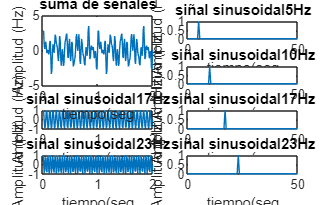

Sf = s1+s2+s3+s4;
subplot(2,2,1)
plot(t,Sf)
title(['suma de señales']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

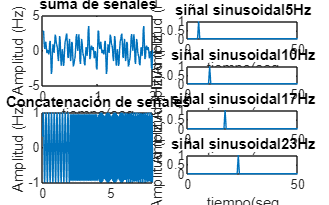

SfC = [s1 s2 s3 s4];
subplot(2,2,3)
plot(t2,SfC)
title(['Concatenación de señales']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

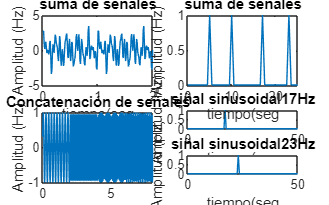


fourSf = fft(Sf);
fourSfC = fft(SfC);

magSf = abs(fourSf/(fs*t(end)));
magSfC = abs(fourSfC/(fs*t2(end)));

normSf = magSf(1:(fs*t(end))/2+1);
normSf(2:end-1) = 2*normSf(2:end-1);

normSfC = magSfC(1:(fs*t2(end))/2+1);
normSfC(2:end-1) = 2*normSfC(2:end-1);

subplot(2,2,2)
plot(F,normSf)
axis([0 25 0 1])
title(['suma de señales']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

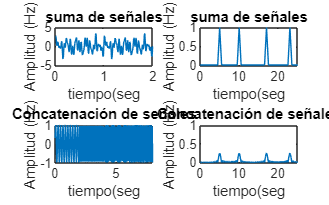

SfC = [s1 s2 s3 s4];
subplot(2,2,4)
plot(F2,normSfC)
axis([0 25 0 1])
title(['Concatenación de señales']);
xlabel('tiempo(seg');
ylabel('Amplitud (Hz)');

clear all
EOG_raw=importdata("E:\Septimo semestre\acondicionamiento de bio señales y bioimagenes\EOG.txt");
eog=EOG_raw(:,1);
fs= 50;
N= length(eog);
t=(1:N)/fs;
plot(t,eog,'k'); hold on;
std_dev=sqrt(sum((eog-mean(eog)).^2)/(N-1));
std_dev1=std(eog);
avg=mean(eog);
disp([std_dev std_dev1])

    0.2524    0.2524



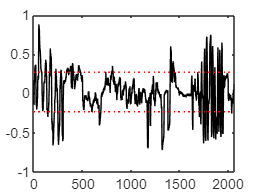

plot([t(1) t(end)], [std_dev+avg std_dev+avg], ':r');
plot([t(1) t(end)], [-std_dev+avg -std_dev+avg], ':r');